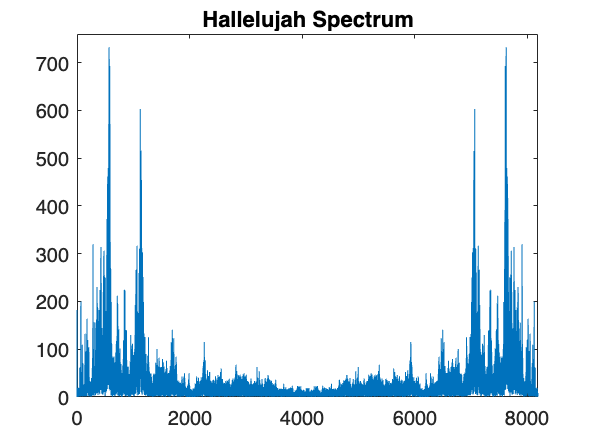

% 
load handel.mat  
x = y'; 
x = x(1:65536);

% Calculate FFT and freq axis 
Y = fft(y); 
freqInc = Fs / length(Y); 
freqAxis = 0:freqInc:(Fs - freqInc); 

% Plot spectrum
plot(freqAxis, abs(Y)) 
title("Hallelujah Spectrum")
axis([0 8191 0 760])

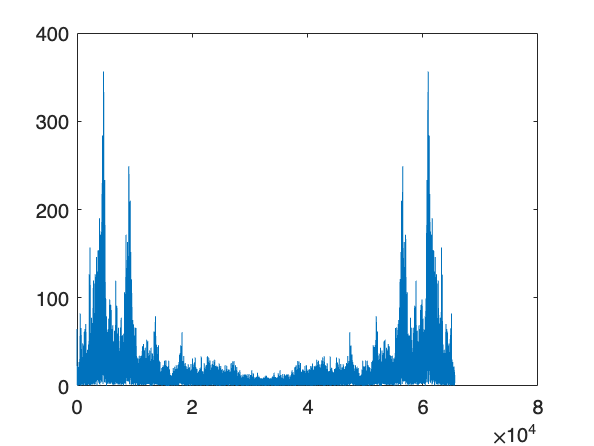


% Downsampling 
y_downsampled = y(1:2:end);
% plot(abs(fft(y_downsampled)))

% Attempt deconstruction and reconstruction
% by windowed FFT 

% Process variables
window_size = 512; 
prev_samps_size = window_size / 2; 
prev_samps = zeros(1, prev_samps_size); 
output = zeros(1, length(x));
half_win_s = (window_size / 2) - 1; 
smooth_win = window(@gausswin, window_size, 2.5)';

% Loop over samples and update window, 
% apply STFT to window, apply IFFT to window, 
% overlap add to output array 
for i = 1:window_size:length(x)  
    % Window is half old samps half new
    w = [prev_samps, x(i:i + half_win_s)]; 
    w = w .* smooth_win;
    % Update previous samples
    prev_samps = x(i:i + half_win_s);
    % Calculate window spectrum 
    W = fft(w); 
    % Analyze spectrum 
    % **************** % 
    % Return to time domain 
    out = ifft(W); 
    output(i:i + half_win_s) = out(1 : half_win_s + 1); 
    output(i + window_size / 2 : i + window_size) = out(window_size / 2:end);
end
plot(abs(fft(output)))

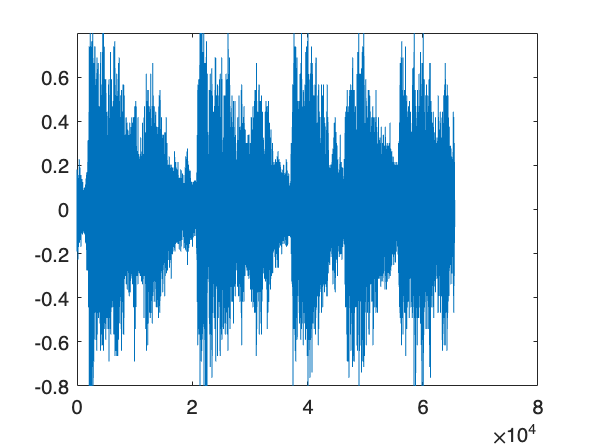

plot(x)

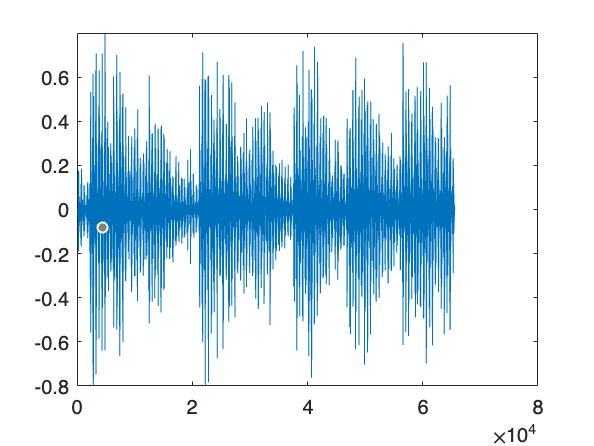

plot(output)